## The CKKS cryptosystem  

clear all
folderPaths = genpath('CKKSClass\');
addpath(folderPaths);

digits(100)         
s = vpa(10)^3;      % scaling factor
q = vpa(10)^15;     % base modulus
L = 2;              % number of levels
N = 4;              % key dimension
setup = Setup(N,q,s,L);
[pk,sk,setup] = KeyGen(setup);

% CKKS ciphertexts
x = vpa(1.2345);
z = Ecd(setup,x,'type','scalar');
z.coefficients

$$ans = \left(\begin{array}{cccc} 0 & 0 & 0 & 1234 \end{array}\right)$$

ct_x = Enc(setup,z,pk)

ct_x =   Ciphertext with properties:

       c0: [1×1 RingElement]
       c1: [1×1 RingElement]
    level: 2
        s: 1000.0
    adapt: 'auto'
       q0: 1000000000000000.0
        P: 1000000000000000000000000000000.0
        L: 2
        Q: 1000000000000000000000
      evk: [1×1 struct]
        q: 1000000000000000000000
        N: 4


y = vpa(4.5678);
zy = Ecd(setup,y,'type','scalar');
ct_y = Enc(setup,zy,pk);

ct_poly =ct_x^4+ct_y^2*(ct_x-ct_y)+ct_y;
p = Dcd(Dec(ct_poly,sk))

$$p = \left(\begin{array}{cccc} 0.11 & -0.27 & -0.614 & -63.368 \end{array}\right)$$

## Plaintext state feedback

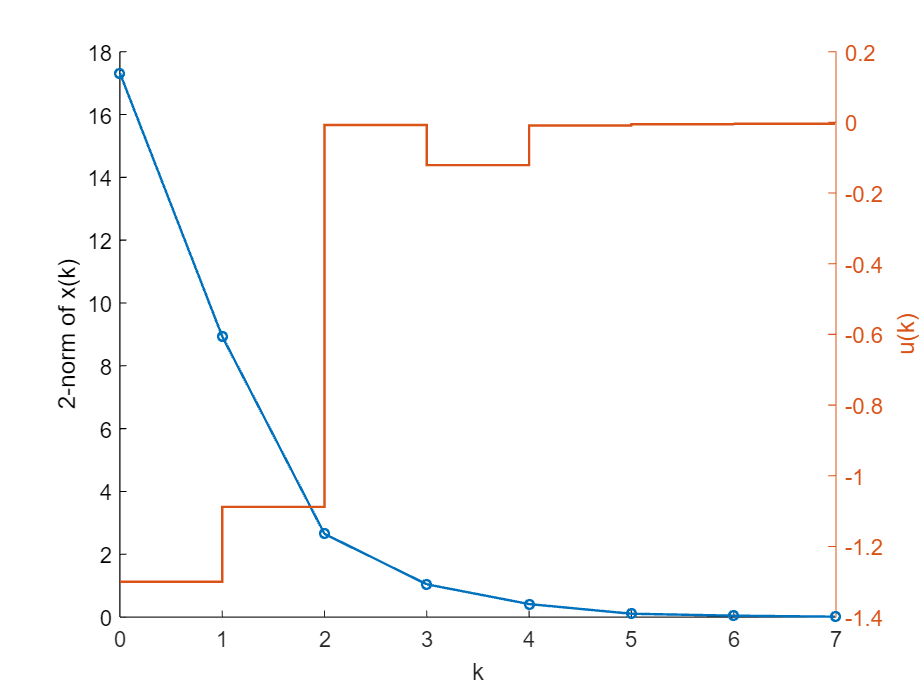

clear x
% system matrices
A = [-0.27  0.24  0.08; 
     -0.20 -0.35 -0.17;
      0.22 -0.02  0.36];
B = [-0.05; 0.11; 0.41];
C = [0 0 1.56];

% controller gain
K = [-0.07 0.06 -0.12];

% initalize
x(:,1) =[10; 10; 10];
kEnd = 8;

% main routine
for k = 1:kEnd
    u(k) = K*x(:,k);
    x(:,k+1) = A*x(:,k)+B*u(k);
end

% plot
figure
hold on
plot(0:kEnd-1,arrayfun(@(cols) norm(x(:,cols),2),1:kEnd),...
    'LineWidth',1.1,'Marker','o','MarkerSize',4)
xlabel('k')
ylabel('2-norm of x(k)')

yyaxis right
stairs(0:kEnd-1,u,'LineWidth',1.1)
ylabel('u(k)')

## Encrypted state feedback

% initialize 
zx = Ecd(setup,x(:,1),'type','scalar');
zK = Ecd(setup,K,'type','scalar');
ct_K = Enc(setup,zK,pk);
ct_x = Enc(setup,zx,pk);

%%
% main routine
for k = 1:kEnd
    if k == 1
        progressbar('Iteration:')      % initialize progressbar
    end
    progressbar(k/kEnd*100)            % update progressbar

    ct_u = ct_K*ct_x;                  % @ cloud
    zu = Dec(ct_u,sk);                 % @ actuator
    p = Dcd(zu);                       % @ actuator
    u(k) = p(end);                     % @ actuator 
    x(:,k+1) = A*x(:,k)+B*u(k);        %   system
    zx(:,k+1) = Ecd(setup,vpa(x(:,k+1)),'type','scalar');
    ct_x = Enc(setup,zx(:,k+1),pk);    % @ sensor

    if k==kEnd
        progressbar('done')             % end progressbar
    end
end

Iteration:


100%    [..........]

done


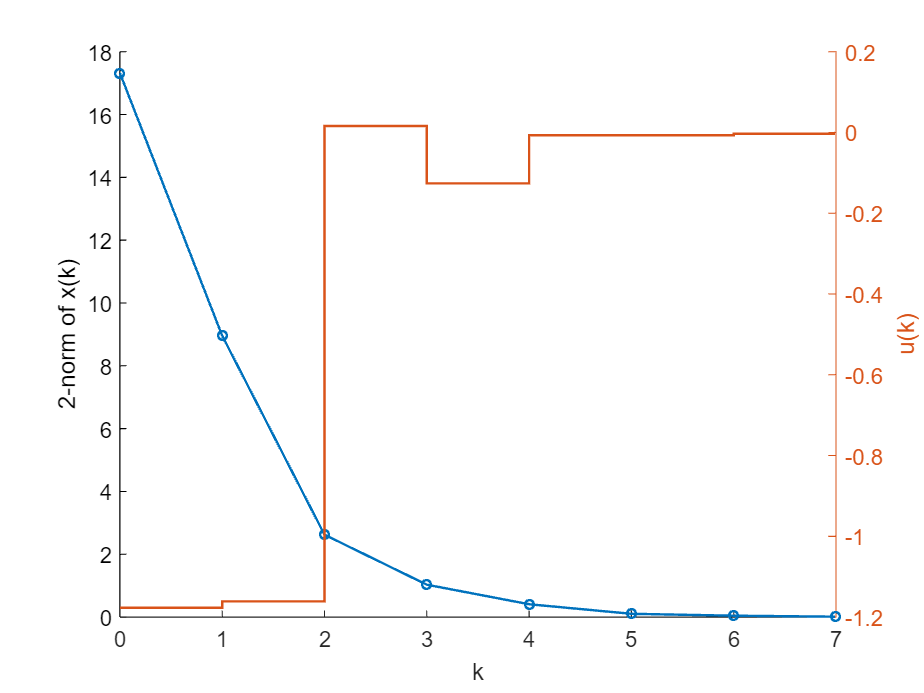

% plot
figure
hold on
plot(0:kEnd-1,arrayfun(@(cols) norm(x(:,cols),2),1:kEnd),...
    'LineWidth',1.1,'Marker','o','MarkerSize',4)
xlabel('k')
ylabel('2-norm of x(k)')

yyaxis right
stairs(0:kEnd-1,u,'LineWidth',1.1)
ylabel('u(k)')

## Plaintext PI control

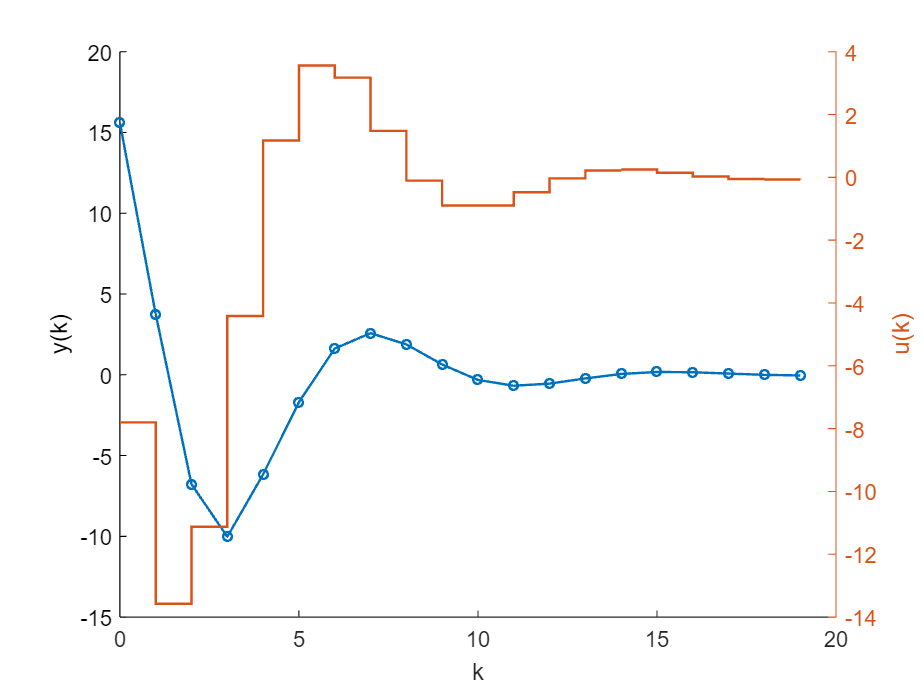

clear x

% controller parameters
dt = 1;
Ki = -0.75;
Kp = -0.5;
    
% initialize
xc = 0;
x(:,1) = [10; 10; 10];
kEnd = 20;

% main routine
for k = 1:kEnd
    y(k) = C*x(:,k);
    u(k) = Ki*xc(k)+Kp*y(k);
    xc(k+1) = xc(k)+dt*y(k);
    x(:,k+1) = A*x(:,k)+B*u(k);
end

% plot
figure
hold on
plot(0:kEnd-1,y,'LineWidth',1.1,'Marker','o','MarkerSize',4)
xlabel('k')
ylabel('y(k)')

yyaxis right
stairs(0:kEnd-1,u,'LineWidth',1.1)
ylabel('u(k)')

## Encrypted PI control

% initialize 
zdt = Ecd(setup,vpa(dt),'type','scalar');
zKi = Ecd(setup,vpa(Ki),'type','scalar');
zKp = Ecd(setup,vpa(Kp),'type','scalar');
zxc = Ecd(setup,xc(:,1),'type','scalar');
ct_dt = Enc(setup,zdt,pk);
ct_Ki = Enc(setup,zKi,pk);
ct_Kp = Enc(setup,zKp,pk);
ct_xc = Enc(setup,zxc,pk);

% main routine
for k = 1:kEnd
    if k == 1
        progressbar('Iteration:')
    end
    progressbar(k/kEnd*100)
   
    y(k) = C*x(:,k);   
    zy = Ecd(setup,vpa(y(k)),'type','scalar');
    ct_y = Enc(setup,zy,pk); 
    ct_u = ct_Ki*ct_xc+ct_Kp*ct_y;
    ct_xc = ct_xc+ct_dt*ct_y;
    zu = Dec(ct_u,sk);
    p = Dcd(zu);
    u(k) = p(end);
    x(:,k+1) = A*x(:,k)+B*u(k);

    if k == kEnd
        progressbar('done')
    end
end

Iteration:

100%    [..........]

done


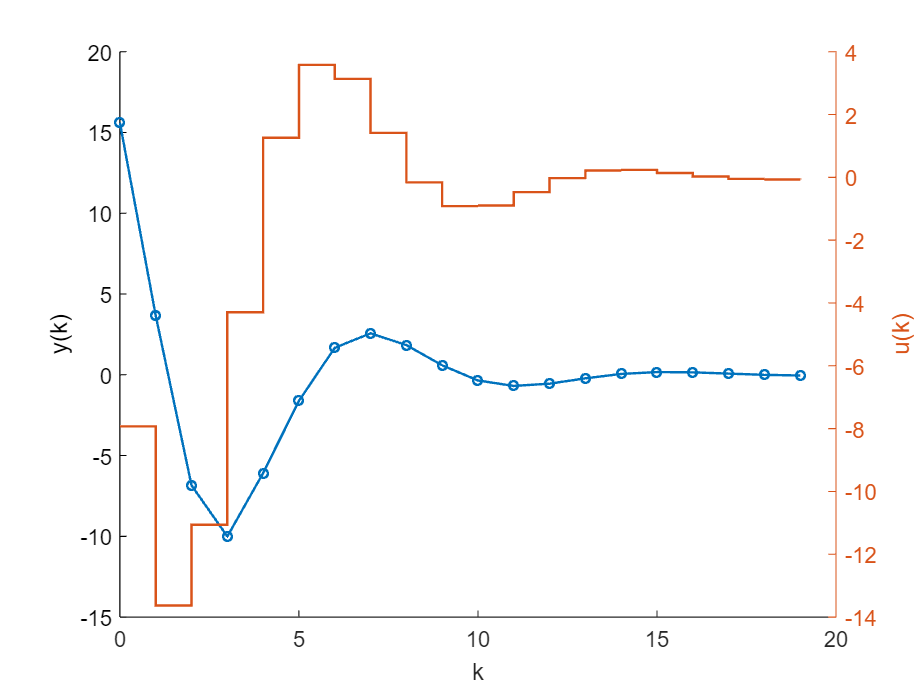

% plot
figure
hold on
plot(0:kEnd-1,y,'LineWidth',1.1,'Marker','o','MarkerSize',4)
xlabel('k')
ylabel('y(k)')

yyaxis right
stairs(0:kEnd-1,u,'LineWidth',1.1)
ylabel('u(k)')